N = 10

N = 10


X = zeros([1,N])

X =      0     0     0     0     0     0     0     0     0     0


X(1) = sum(linspace(0,N-1,N))

X =     45     0     0     0     0     0     0     0     0     0


for k = 1:N-1
    a1 = 1
    a2 = -(N+1) * exp(-2j * pi * k);
    a3 = N * exp(-2j * pi* k * ((N+1)/N));
    
    b1 = (exp(2j*(pi/N)*k) - 1)^2;
    

    X(k+1) = -1*(a1+a2+a3)/(b1);
end

a1 = 1

a1 = 1

a1 = 1

a1 = 1

a1 = 1

a1 = 1

a1 = 1

a1 = 1

a1 = 1

subplot(1,2,1)
disp(X)

  45.0000 + 0.0000i -13.0902 - 9.5106i  -8.0902 + 2.6287i  -1.9098 + 5.8779i   3.0902 + 4.2533i   5.0000 - 0.0000i   3.0902 - 4.2533i  -1.9098 - 5.8779i  -8.0902 - 2.6287i -13.0902 + 9.5106i



stem(abs(X))
subplot(1,2,2)
disp(fft(linspace(0,N-1,N)))

  45.0000 + 0.0000i  -5.0000 +15.3884i  -5.0000 + 6.8819i  -5.0000 + 3.6327i  -5.0000 + 1.6246i  -5.0000 + 0.0000i  -5.0000 - 1.6246i  -5.0000 - 3.6327i  -5.0000 - 6.8819i  -5.0000 -15.3884i



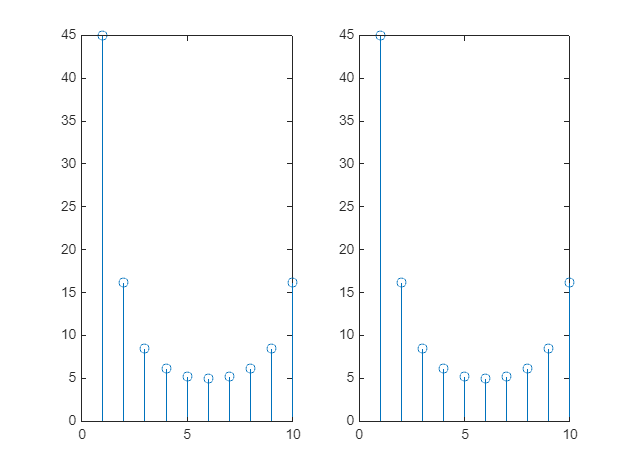

stem(abs(fft(linspace(0,N-1,N))))

clf;

disp(X)

  45.0000 + 0.0000i -13.0902 - 9.5106i  -8.0902 + 2.6287i  -1.9098 + 5.8779i   3.0902 + 4.2533i   5.0000 - 0.0000i   3.0902 - 4.2533i  -1.9098 - 5.8779i  -8.0902 - 2.6287i -13.0902 + 9.5106i



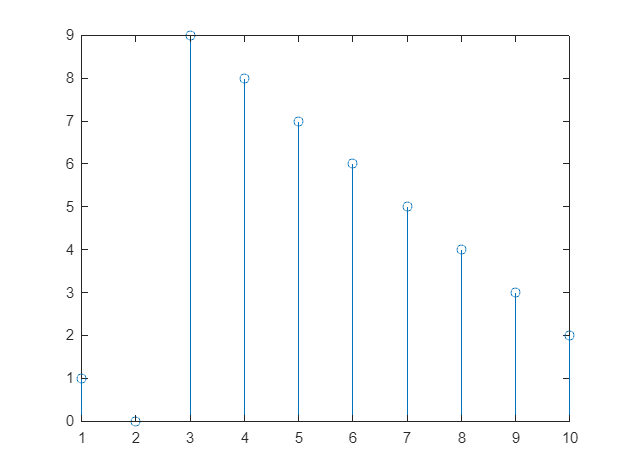

stem(abs(ifft(X)))